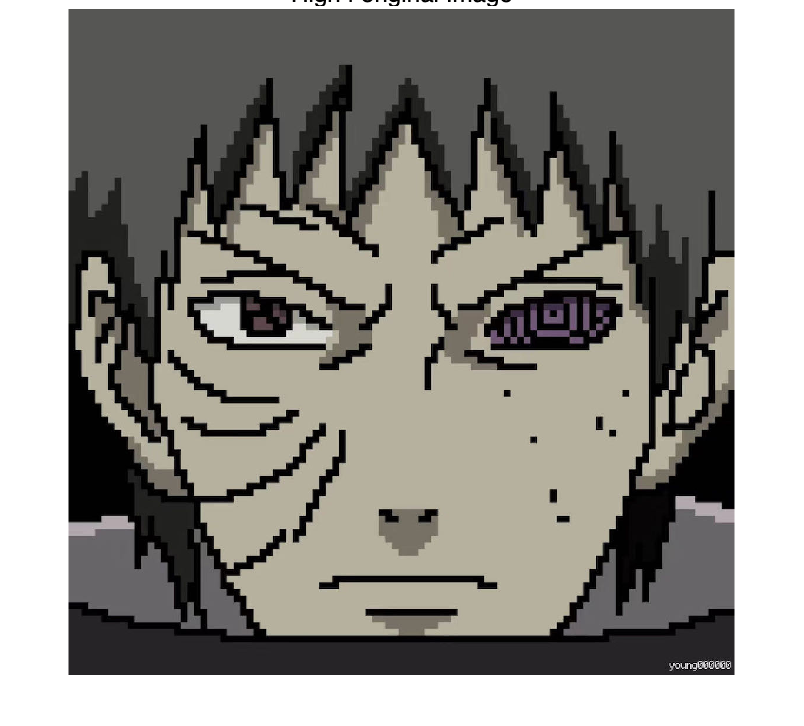

clear all;
clc;

high_frequency = double(imread('带土.jpeg'));
low_frequency = double(imread('白面具.jpeg'));

iternum = 5;% number of layer
cut_frequency = 4;

if (size(high_frequency) ~= size(low_frequency))
    error('Input images are not the same size!')
end

% high-pass pyramid and low-pass pyramid
high_pyramid = LaplacianPyramid(high_frequency, iternum);
low_pyramid = LaplacianPyramid(low_frequency, iternum);

% TODO: get blend laplacian pyramid
blend_pyramid = cell(iternum, 1);
for i = 1:cut_frequency
    blend_pyramid{i} = high_pyramid{i};
end

for i = cut_frequency+1:iternum
    blend_pyramid{i} = low_pyramid{i};
end

blendImage = LaplacianReconstruct(blend_pyramid);
blendImage = uint8(blendImage);
vis = vis_hybrid_image(blendImage);

figure;
imshow(uint8(high_frequency));
title('High f original Image');

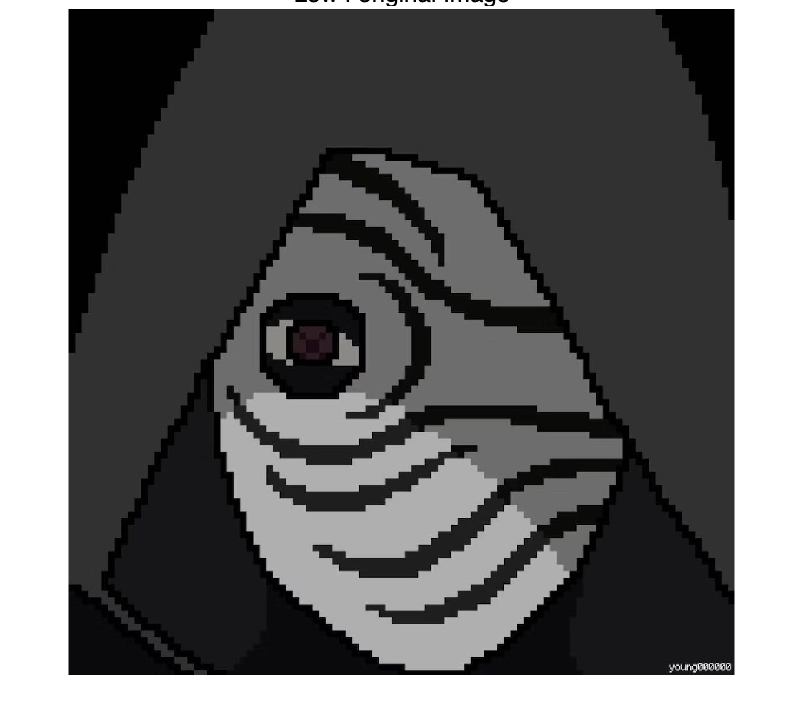

figure;
imshow(uint8(low_frequency));
title('Low f original Image');

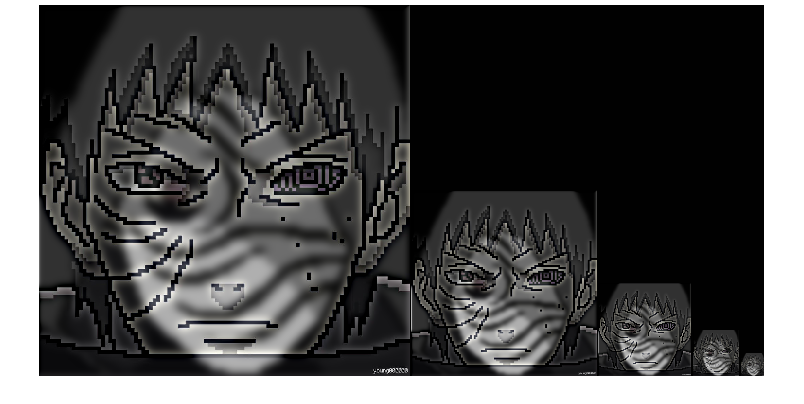

figure;
imshow(vis);
title('hybrid_Image');

imwrite(vis, 'hybrid_image_2.jpg', 'quality', 95);


